# Nordic Seas cyclone plotting script

## Reading in all years of data to create nested directories

% Specify the folder where the files live
myFolder = 'C:\Users\terri\Documents\MATLAB\ERA5Nordic'

myFolder = 'C:\Users\terri\Documents\MATLAB\ERA5Nordic'

% Check to make sure the folder actually exists. Warn user if it doesn't
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s\nPlease specify a new folder.', myFolder);
    uiwait(warndlg(errorMessage));
    myFolder = uigetdir(); % Ask for a new one.
    if myFolder == 0
         % User clicked Cancel
         return;
    end
end

% Create struct containing tables for each year's data.
filePattern = fullfile(myFolder, '*.csv');
ERA5Nordic = dir(filePattern);
n = length(ERA5Nordic);

for ix = 1:n
    baseFileName = ERA5Nordic(ix).name;
    fullFileName = fullfile(ERA5Nordic(ix).folder, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    [ERA5Nordic(ix).Data] = readtable(fullFileName);
end

baseFileName = '2002_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2002_ERA5_Nordic_Candidates.csv


baseFileName = '2003_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2003_ERA5_Nordic_Candidates.csv


baseFileName = '2004_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2004_ERA5_Nordic_Candidates.csv


baseFileName = '2005_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2005_ERA5_Nordic_Candidates.csv


baseFileName = '2006_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2006_ERA5_Nordic_Candidates.csv


baseFileName = '2007_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2007_ERA5_Nordic_Candidates.csv


baseFileName = '2008_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2008_ERA5_Nordic_Candidates.csv


baseFileName = '2009_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2009_ERA5_Nordic_Candidates.csv


baseFileName = '2010_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2010_ERA5_Nordic_Candidates.csv


baseFileName = '2011_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2011_ERA5_Nordic_Candidates.csv


baseFileName = '2012_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2012_ERA5_Nordic_Candidates.csv


baseFileName = '2013_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2013_ERA5_Nordic_Candidates.csv


baseFileName = '2014_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2014_ERA5_Nordic_Candidates.csv


baseFileName = '2015_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2015_ERA5_Nordic_Candidates.csv


baseFileName = '2016_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2016_ERA5_Nordic_Candidates.csv


baseFileName = '2017_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2017_ERA5_Nordic_Candidates.csv


baseFileName = '2018_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2018_ERA5_Nordic_Candidates.csv


baseFileName = '2019_ERA5_Nordic_Candidates.csv'

Now reading C:\Users\terri\Documents\MATLAB\ERA5Nordic\2019_ERA5_Nordic_Candidates.csv



% Masking longitude values into -180 to 180
for ii = 1:18
    [rows, cols] = size(ERA5Nordic(ii).Data);
    NordicCandidatesA = table2array(ERA5Nordic(ii).Data);
    for k = 1:rows
        if NordicCandidatesA(k,8) > 180
            NordicCandidatesA(k,8) = (NordicCandidatesA(k,8)-360);
            ERA5Nordic(ii).Data = array2table(NordicCandidatesA);
            ERA5Nordic(ii).Data = renamevars(ERA5Nordic(ii).Data,["NordicCandidatesA1","NordicCandidatesA2","NordicCandidatesA3","NordicCandidatesA4","NordicCandidatesA5","NordicCandidatesA6","NordicCandidatesA7","NordicCandidatesA8","NordicCandidatesA9","NordicCandidatesA10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
        end
    end
end

% Fix variable names in tables
for iz = 1:18
    ERA5Nordic(iz).Data = renamevars(ERA5Nordic(iz).Data,["Var1","Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
end     % don't worry about the error that shows up for the previous line

Error using tabular/renamevars (line 46)
Unrecognized table variable name 'Var1'.

## Import data (single year)

opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "msl"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
NordicCandidates2019 = readtable("C:\Users\terri\Documents\MATLAB\ERA5Nordic\2019_ERA5_Nordic_Candidates.csv", opts);
clear opts

## Masking longitude values into -180 - 180 (single year)

[rows, cols] = size(NordicCandidates2019);
NordicCandidatesA = table2array(NordicCandidates2019);
for k = 1:rows
    if NordicCandidatesA(k,8) > 180
        NordicCandidatesA(k,8) = (NordicCandidatesA(k,8)-360);
        NordicCandidates2019 = array2table(NordicCandidatesA);
        NordicCandidates2019 = renamevars(NordicCandidates2019,["NordicCandidatesA1","NordicCandidatesA2","NordicCandidatesA3","NordicCandidatesA4","NordicCandidatesA5","NordicCandidatesA6","NordicCandidatesA7","NordicCandidatesA8","NordicCandidatesA9","NordicCandidatesA10"],["track_id","year","month","day","hour","i","j","lon","lat","VarName10"]);
    end
end

% wrapTo180(NordicCandidates.lon)

## Plots to make

% One that shows tracks for different months in different colours (and also has intensity?)

% One that colour codes tracks in bins by intensity within months or seasons
% for the latter, define new tables that filter/sort tracks by intensity,
% maybe plotting the top10storms or sorting strong/weak and plotting all strong storms. can do within the
% month tables, potentially. for DJF of certain years this would be good

## Making the figure, tracks colour coded by month!!!

j = max(ERA5Nordic(xx).Data.track_id);
s = {'2002 Nordic Seas ERA5','2003 Nordic Seas ERA5','2004 Nordic Seas ERA5','2005 Nordic Seas ERA5','2006 Nordic Seas ERA5','2007 Nordic Seas ERA5','2008 Nordic Seas ERA5','2009 Nordic Seas ERA5','2010 Nordic Seas ERA5','2011 Nordic Seas ERA5','2012 Nordic Seas ERA5','2013 Nordic Seas ERA5','2014 Nordic Seas ERA5','2015 Nordic Seas ERA5','2016 Nordic Seas ERA5','2017 Nordic Seas ERA5','2018 Nordic Seas ERA5','2019 Nordic Seas ERA5'};

for xx = 1:18
    Jan = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 1, :); % Defining tables for each month's data
    Feb = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 2, :);
    Mar = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 3, :);
    Apr = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 4, :);
    May = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 5, :);
    Jun = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 6, :);
    Jul = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 7, :);
    Aug = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 8, :);
    Sep = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 9, :);
    Oct = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 10, :);
    Nov = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 11, :);
    Dec = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 12, :);
    for b = 0:j
        latJan = Jan.lat(Jan.track_id == b);
        lonJan = Jan.lon(Jan.track_id == b);
        geoplot(latJan,lonJan,'.-','Color',cc(1,:)); % colours specified so that DJF will be easy to visualize
        hold on
        latFeb = Feb.lat(Feb.track_id == b);
        lonFeb = Feb.lon(Feb.track_id == b);
        geoplot(latFeb,lonFeb,'.-','Color',dd(7,:));
        hold on 
        latMar = Mar.lat(Mar.track_id == b);
        lonMar = Mar.lon(Mar.track_id == b);
        geoplot(latMar,lonMar,'.-','Color',cc(4,:));
        hold on 
        latApr = Apr.lat(Apr.track_id == b);
        lonApr = Apr.lon(Apr.track_id == b);
        geoplot(latApr,lonApr,'.-','Color',cc(3,:));
        hold on 
        latMay = May.lat(May.track_id == b);
        lonMay = May.lon(May.track_id == b);
        geoplot(latMay,lonMay,'.-','Color',cc(6,:));
        hold on 
        latJun = Jun.lat(Jun.track_id == b);
        lonJun = Jun.lon(Jun.track_id == b);
        geoplot(latJun,lonJun,'.-','Color',cc(8,:));
        hold on 
        latJul = Jul.lat(Jul.track_id == b);
        lonJul = Jul.lon(Jul.track_id == b);
        geoplot(latJul,lonJul,'.-','Color',cc(12,:));
        hold on 
        latAug = Aug.lat(Aug.track_id == b);
        lonAug = Aug.lon(Aug.track_id == b);
        geoplot(latAug,lonAug,'.-','Color',cc(10,:));
        hold on 
        latSep = Sep.lat(Sep.track_id == b);
        lonSep = Sep.lon(Sep.track_id == b);
        geoplot(latSep,lonSep,'.-','Color',cc(7,:));
        hold on 
        latOct = Oct.lat(Oct.track_id == b);
        lonOct = Oct.lon(Oct.track_id == b);
        geoplot(latOct,lonOct,'.-','Color',cc(11,:));
        hold on 
        latNov = Nov.lat(Nov.track_id == b);
        lonNov = Nov.lon(Nov.track_id == b);
        geoplot(latNov,lonNov,'.-','Color',cc(9,:));
        hold on 
        latDec = Dec.lat(Dec.track_id == b);
        lonDec = Dec.lon(Dec.track_id == b);
        geoplot(latDec,lonDec,'.-','Color',cc(5,:));
        hold on
        geolimits([61 81],[-36 19.5])
    end
    geobasemap('topographic')
    title(s(xx))
    exportgraphics(gca,['Tracks' num2str(xx+2001) 'NordicERA5.png'],"Resolution",300);
    clf
end

## Exporting the figure

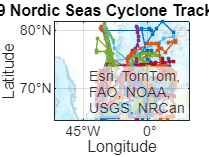

exportgraphics(gca,"NordicERA52019.png","Resolution",300)

## Monthly plots

% month1 = NordicCandidates((month=1),:)
% for month1 = 1:12
%     for c = 0:j
%         lat3 = NordicCandidates.lat(NordicCandidates.track_id == c);
%         lon3 = NordicCandidates.lon(NordicCandidates.track_id == c);
%         geoplot(lat3,lon3,'.-')
%         geolimits([61 81],[324 360]) % FIX THIS
%         geobasemap('colorterrain')
%         title(['month',num2str(month),'tracks'])
%     end
% end

% for c = 0:j
%     switch NordicCandidates.month 
%         case 1
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 2
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 3
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 4
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 5
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 6
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 7
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 8
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 9
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 10
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 11
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 12
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%     end
% end

## Defining tables for each month's data

Jan = NordicCandidates2019(NordicCandidates2019.month == 1, :);
Feb = NordicCandidates2019(NordicCandidates2019.month == 2, :);
Mar = NordicCandidates2019(NordicCandidates2019.month == 3, :);
Apr = NordicCandidates2019(NordicCandidates2019.month == 4, :);
May = NordicCandidates2019(NordicCandidates2019.month == 5, :);
Jun = NordicCandidates2019(NordicCandidates2019.month == 6, :);
Jul = NordicCandidates2019(NordicCandidates2019.month == 7, :);
Aug = NordicCandidates2019(NordicCandidates2019.month == 8, :);
Sep = NordicCandidates2019(NordicCandidates2019.month == 9, :);
Oct = NordicCandidates2019(NordicCandidates2019.month == 10, :);
Nov = NordicCandidates2019(NordicCandidates2019.month == 11, :);
Dec = NordicCandidates2019(NordicCandidates2019.month == 12, :);

## Monthly plots

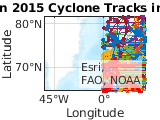

k = max(Jan.track_id);
for d = 0:k
    latj = Jan.lat(Jan.track_id == d);
    lonj = Jan.lon(Jan.track_id == d);
    geoplot(latj,lonj,'.- red')
    geolimits([61 81],[324 20])
    hold on
end
geobasemap('topographic')
title('Jan 2015 Cyclone Tracks in ERA5')